# **KINOVA Gen3 Manipulator Path Planning using STOMP**

This example shows how to plan a collision-free robot path from an initial to a desired end-effector pose using STOMP ([Stochastic trajectory optimization for motion planning](https://ieeexplore.ieee.org/document/5980280))[1].

## Robot Description and Poses

Load the KINOVA Gen3 rigid body tree (RBT) model.

robot_name = 'universalUR5';
robot = loadrobot(robot_name, 'DataFormat', 'column'); % Note there are different data formats for loading the robot (chosen in the 2nd argument)

Get the number of joints.

numJoints = numel(homeConfiguration(robot));

Specify the robot frame where the end-effector is attached.

endEffector = "tool0"; 

Specify initial and desired end-effector poses. Use inverse kinematics to solve for the initial robot configuration given a desired pose.

% Initial end-effector pose
taskInit = trvec2tform([[0.6 0.0 0.1]])*axang2tform([0 1 0 pi]);

% Compute current robot joint configuration using inverse kinematics
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = ik(endEffector, taskInit, weights, robot.homeConfiguration);

% The IK solver respects joint limits, but for those joints with infinite
% range, they must be wrapped to a finite range on the interval [-pi, pi].
% Since the the other joints are already bounded within this range, it is
% sufficient to simply call wrapToPi on the entire robot configuration
% rather than only on the joints with infinite range.
currentRobotJConfig = wrapToPi(currentRobotJConfig);

% Final (desired) end-effector pose
taskFinal = trvec2tform([0.2 0.6 0.35])*axang2tform([0 1 0 pi]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal']; % 6x1 vector for final pose: [x, y, z, phi, theta, psi]

% Final configuration
finalRobotJConfig = ik(endEffector, taskFinal, weights, currentRobotJConfig);
finalRobotJConfig = wrapToPi(finalRobotJConfig);

## Collision Meshes and Obstacles

MATLAB has its own collision world functions to check for and avoid collisions (e.g., collisionSphere, collisionBox, etc). Here, we follow the STOMP paper to set up the voxel world and using the signed Euclidean distance function for this purpose, which is a common practice in robotics perception, mapping, and collision avoidance. We shall still use the MATLAB built-in collision object functions to visualize the object for the convenience. See more details in the following helper functions.

helperCreateObstaclesKINOVA;

Visualize the robot at the initial configuration. You should see the obstacles in the environment as well.

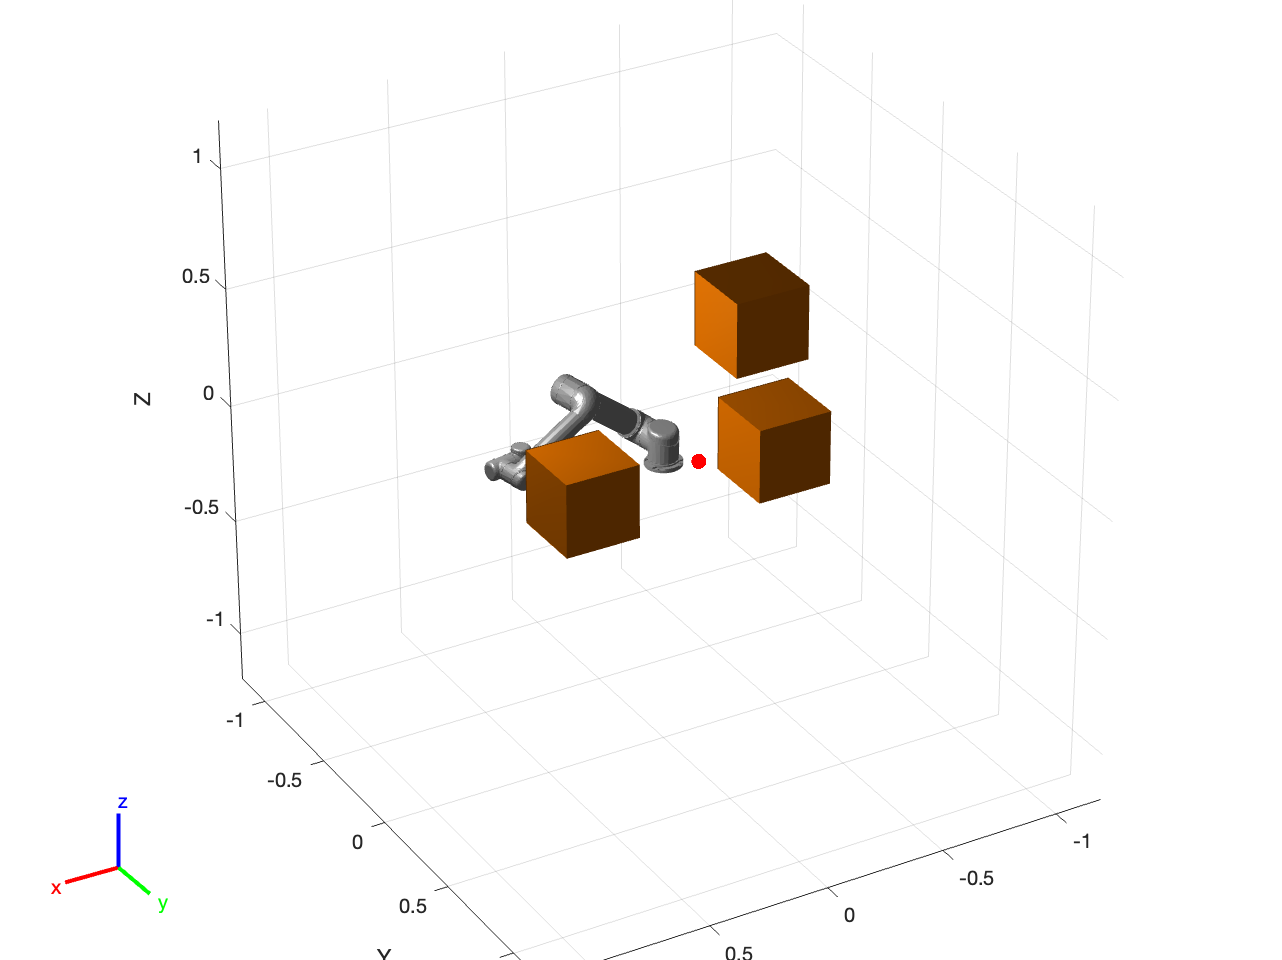

x0 = [currentRobotJConfig', zeros(1,numJoints)];
helperInitialVisualizerKINOVA;

Specify a safety distance away from the obstacles. This value is used in the inequality constraint function of the nonlinear MPC controller.

safetyDistance = 0.01; 

## Path Planning using STOMP

The following helper function contain the setup and execution of the STOMP algorithm for collision-avoidance planning.

Elapsed time is 0.832993 seconds.


Qtheta = 1.9383e+04

RAR = 80.8466

Elapsed time is 0.795672 seconds.


Qtheta = 1.9382e+04

RAR = 80.8555

Elapsed time is 0.781723 seconds.


Qtheta = 1.9370e+04

RAR = 80.8673

Elapsed time is 0.698238 seconds.


Qtheta = 1.9372e+04

RAR = 80.8717

Elapsed time is 0.705105 seconds.


Qtheta = 1.9353e+04

RAR = 80.8748

Elapsed time is 0.816886 seconds.


Qtheta = 1.9333e+04

RAR = 80.8642

Elapsed time is 0.719281 seconds.


Qtheta = 1.9313e+04

RAR = 80.8685

Elapsed time is 0.672952 seconds.


Qtheta = 1.9290e+04

RAR = 80.8704

Elapsed time is 0.777652 seconds.


Qtheta = 1.9264e+04

RAR = 80.8710

Elapsed time is 0.732787 seconds.


Qtheta = 1.9227e+04

RAR = 80.8653

Elapsed time is 0.729780 seconds.


Qtheta = 1.9203e+04

RAR = 80.8704

Elapsed time is 0.866008 seconds.


Qtheta = 1.9187e+04

RAR = 80.8927

Elapsed time is 0.739895 seconds.


Qtheta = 1.9165e+04

RAR = 80.8805

Elapsed time is 0.728053 seconds.


Qtheta = 1.9154e+04

RAR = 80.8767

Elapsed time is 0.787104 seconds.


Qtheta = 1.9126e+04

RAR = 80.8880

Elapsed time is 0.770104 seconds.


Qtheta = 1.9111e+04

RAR = 80.8865

Elapsed time is 0.816921 seconds.


Qtheta = 1.9110e+04

RAR = 80.8893

Elapsed time is 0.873742 seconds.


Qtheta = 1.9109e+04

RAR = 80.8885

Elapsed time is 0.735106 seconds.


Qtheta = 1.9108e+04

RAR = 80.8890

Elapsed time is 0.763506 seconds.


Qtheta = 1.9107e+04

RAR = 80.8844

Elapsed time is 0.878288 seconds.


Qtheta = 1.9108e+04

RAR = 80.8741

Elapsed time is 0.772047 seconds.


Qtheta = 1.9109e+04

RAR = 80.8865

Elapsed time is 0.749184 seconds.


Qtheta = 1.9108e+04

RAR = 80.8922

Elapsed time is 0.842689 seconds.


Qtheta = 1.9109e+04

RAR = 80.8969

Elapsed time is 0.724160 seconds.


Qtheta = 1.9110e+04

RAR = 80.9034

Elapsed time is 0.717986 seconds.


Qtheta = 1.9110e+04

RAR = 80.9067

Elapsed time is 0.755384 seconds.


Qtheta = 1.9110e+04

RAR = 80.9027

Elapsed time is 0.742977 seconds.


Qtheta = 1.9110e+04

RAR = 80.8967

Elapsed time is 0.683604 seconds.


Qtheta = 1.9110e+04

RAR = 80.9039

Elapsed time is 0.839172 seconds.


Qtheta = 1.9111e+04

RAR = 80.9020

Elapsed time is 0.741489 seconds.


Qtheta = 1.9111e+04

RAR = 80.8843

Elapsed time is 0.724000 seconds.


Qtheta = 1.9110e+04

RAR = 80.8848

Elapsed time is 0.844125 seconds.


Qtheta = 1.9111e+04

RAR = 80.9017

Elapsed time is 0.771845 seconds.


Qtheta = 1.9111e+04

RAR = 80.9163

Elapsed time is 0.686829 seconds.


Qtheta = 1.9110e+04

RAR = 80.9040

Elapsed time is 0.791977 seconds.


Qtheta = 1.9111e+04

RAR = 80.9094

Elapsed time is 0.807274 seconds.


Qtheta = 1.9111e+04

RAR = 80.9085

Elapsed time is 0.700908 seconds.


Qtheta = 1.9112e+04

RAR = 80.9173

Elapsed time is 0.818174 seconds.


Qtheta = 1.9112e+04

RAR = 80.9223

Elapsed time is 0.839515 seconds.


Qtheta = 1.9112e+04

RAR = 80.9218

Elapsed time is 0.728093 seconds.


Qtheta = 1.9109e+04

RAR = 80.9256

Elapsed time is 0.794476 seconds.


Qtheta = 1.9112e+04

RAR = 80.9272

Elapsed time is 0.823204 seconds.


Qtheta = 1.9111e+04

RAR = 80.9210

Elapsed time is 0.692954 seconds.


Qtheta = 1.9109e+04

RAR = 80.9347

Elapsed time is 0.743770 seconds.


Qtheta = 1.9110e+04

RAR = 80.9543

Elapsed time is 0.744145 seconds.


Qtheta = 1.9109e+04

RAR = 80.9607

Elapsed time is 0.747288 seconds.


Qtheta = 1.9109e+04

RAR = 80.9639

Elapsed time is 0.691082 seconds.


Qtheta = 1.9109e+04

RAR = 80.9756

Elapsed time is 0.798759 seconds.


Qtheta = 1.9108e+04

RAR = 80.9847

Elapsed time is 0.728309 seconds.


Qtheta = 1.9108e+04

RAR = 80.9887

Elapsed time is 0.673014 seconds.


Qtheta = 1.9109e+04

RAR = 80.9775

Maximum iteration (50) has reached.
STOMP Finished.


isTrajectoryInCollision = logical
   0


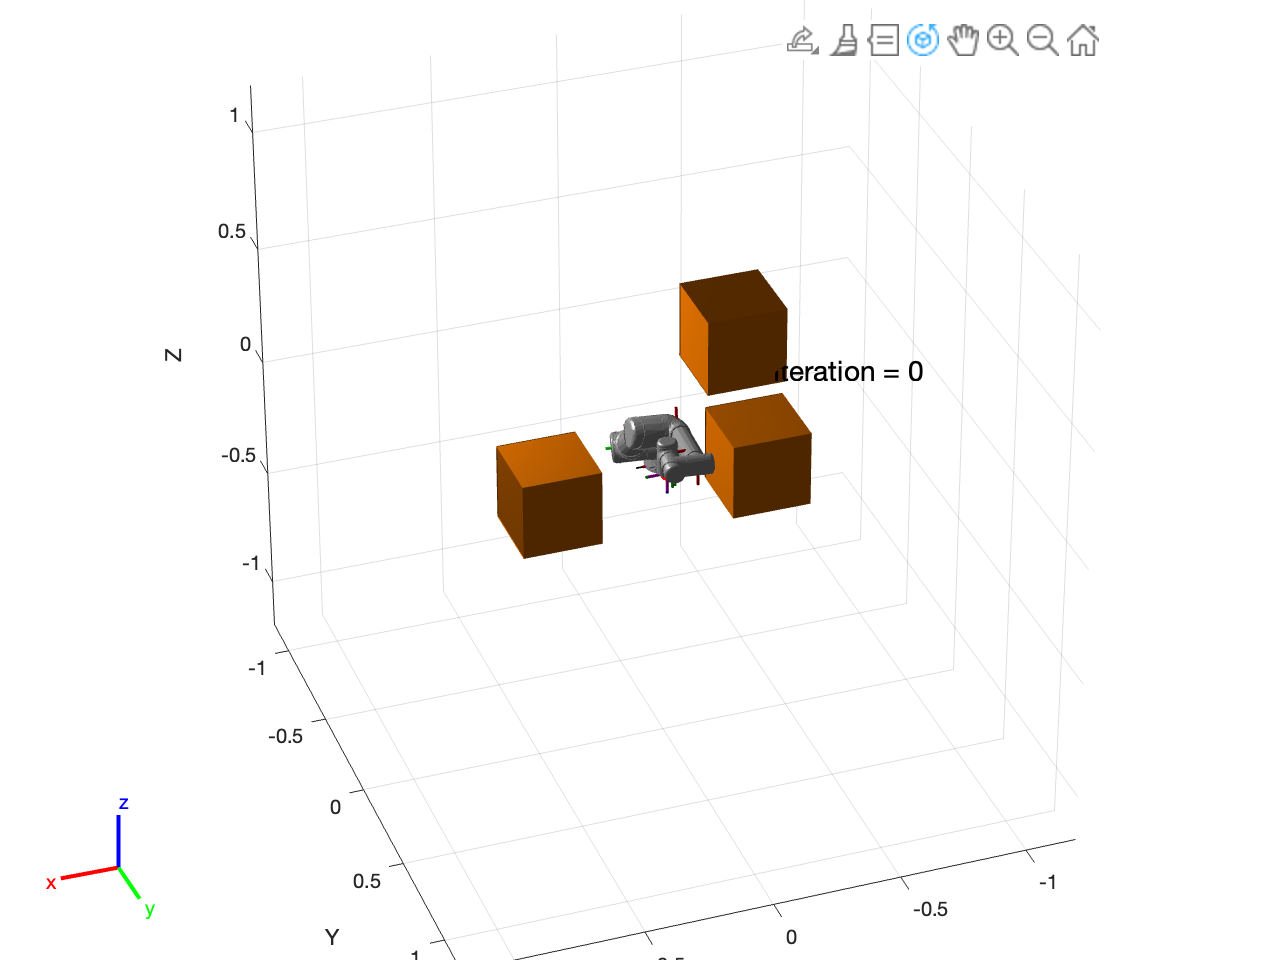

helperSTOMP;

[1] M. Kalakrishnan, S. Chitta, E. Theodorou, P. Pastor and S. Schaal, "STOMP: Stochastic trajectory optimization for motion planning," *2011 IEEE International Conference on Robotics and Automation*, 2011, pp. 4569-4574, doi: 10.1109/ICRA.2011.5980280.